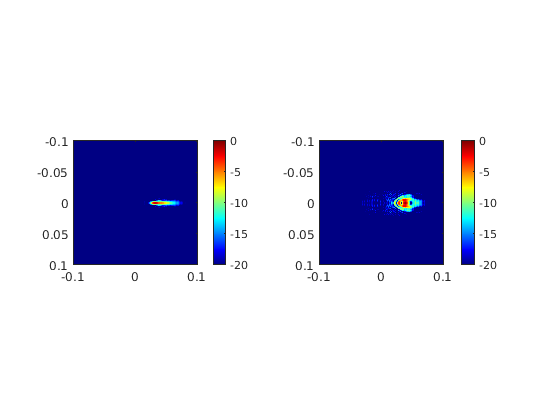

close all;
format long;
addpath('./Classes');
addpath('./HornData/Dist56');


lambda = 1e-3;
k0 = 2*pi/lambda;
antenna_r = 10e-3;
dx = 0.5*lambda;
L = 200e-3;
M = L/dx + 1;
z1 = 56e-3;
z2 = 40e-3;
dblim = -25;

% Instantiate classes
p = Propagator(L, lambda, dx);
l = Lens(L, lambda, dx);
loptim = LensOptimizer(L, lambda, dx, z1, z2, antenna_r);

% quick lambda function
normdb = @(u1) mag2db(abs(u1)) - max(max(mag2db(abs(u1))));


hornangle = 40;


pointsource = p.pso(hornangle, 0, z1);
u0_phase = angle(p.prop(pointsource, z1*sind(hornangle)));


ampdata = readmatrix(int2str(hornangle)+"deg_Amp");
phasedata = readmatrix(int2str(hornangle)+"deg_Phase");
phasedata = deg2rad(phasedata);

% horn setup
hornx = 1e-3*(-10:0.2:10);
horny = 1e-3*(-10:0.2:10);
[Hornx, Horny] = meshgrid(hornx, horny);
[xx, yy] = meshgrid(p.x, p.y);

u0_amp = interp2(Hornx, Horny, ampdata, xx, yy, 'nearest', 0);
u0 = u0_amp.*exp(1i.*u0_phase);

% optim setup:
% ideal focus
demou1 = loptim.idealcpu1(40,0);
ndemou1 = normdb(demou1);
ndemou1csection = ndemou1(ceil(M/2),:);
ndemou1(ndemou1 < dblim) = dblim;
% regular lens
cplens = l.makecplens(z1, z2, antenna_r, 1);
cpu1 = l.lenspropagate(u0, cplens, 0, z2);
ncpu1 = normdb(cpu1);
ncpu1csection = ncpu1(ceil(M/2),:);
ncpu1(ncpu1 < dblim) = dblim;
% benchmarks
cpdbtotal = sum(ncpu1, 'all');
cperror = immse(ndemou1, ncpu1);

% initialize coefficients
coeffs = [-10.795 28.8898 -2.8194 10.7438 -2.1028];
% aperlens = l.makephaselens(coeffs, antenna_r, 1);   
% training
steps = 100;
lr = 1e-3;
prev_error = 1e6;
aperlens = l.makephaselens(coeffs, antenna_r, 1);
apu1 = l.lenspropagate(u0, aperlens, 0, z2);

napu1 = normdb(apu1);




% figure;
% imagesc(p.x, p.y, normdb(demou1));
% caxis([-20 0]);
% axis square;
% colormap jet;
% colorbar;


figure;
subplot(121);
imagesc(p.x, p.y, ncpu1);
caxis([-20 0]);
axis square;
colormap jet;
colorbar;

subplot(122);
imagesc(p.x, p.y, napu1);
axis square;
colormap jet;
caxis([-20 0]);
colorbar;

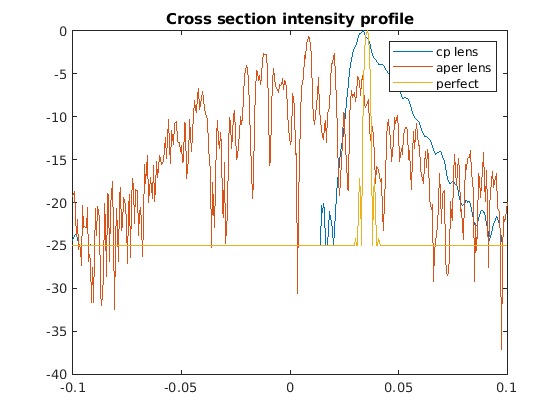


figure('Name', 'Cross section');
plot(p.x, ncpu1(ceil(M/2),:));
hold on;
plot(p.x, napu1csection);
plot(p.x, ndemou1(ceil(M/2),:));
hold off;
legend("cp lens", "aper lens", "perfect");
title("Cross section intensity profile");